## PRÁCTICA 2 DE MOTORES VOLUMÉTRICOS

## Lectura de datos

% Especifica la ruta de tu archivo de texto
ruta_archivo = 'C:\Users\Marco\OneDrive - Universidad Politécnica de Madrid\GITI\CUARTO AÑO\Segundo semestre\Motores Volumétricos\Práctica\Práctica 2/test_23abril24.txt';

% Utiliza la función importdata para cargar el archivo de texto. 

% Cambiar la extensión de lvm a txt y eliminar todas las filas que no aportan información.
% Dejar información a partir de Y_Unit_Label, X_Unit_Label, X_value,
% presión... con todas sus filas.
datos = readtable(ruta_archivo, 'Delimiter', '\t','VariableNamingRule', 'preserve');

## Gráficas de todos los datos

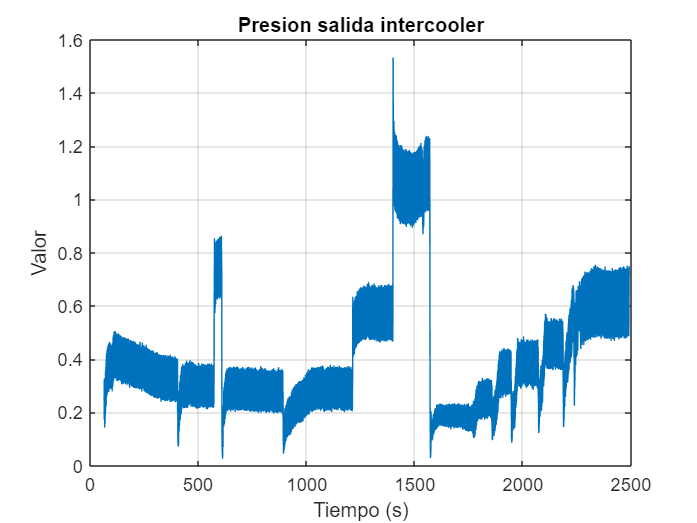

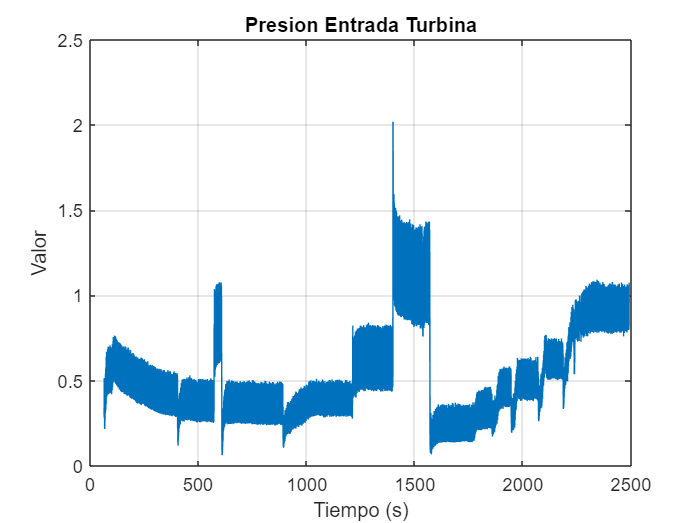

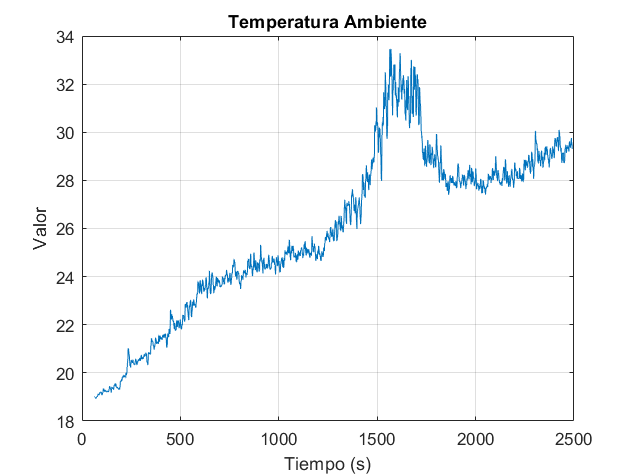

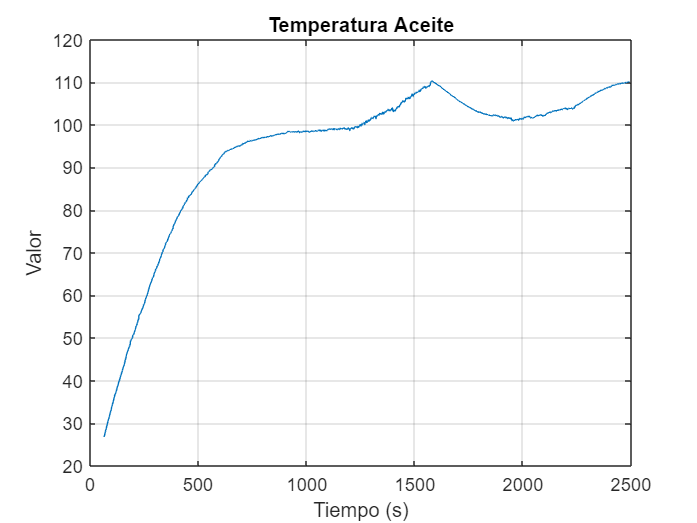

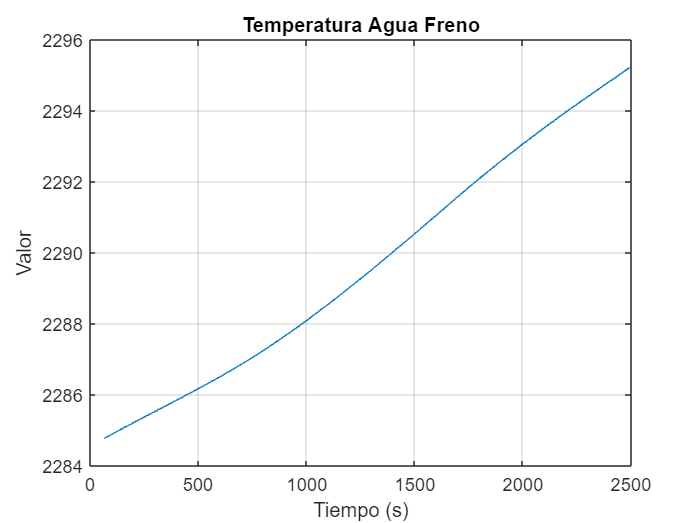

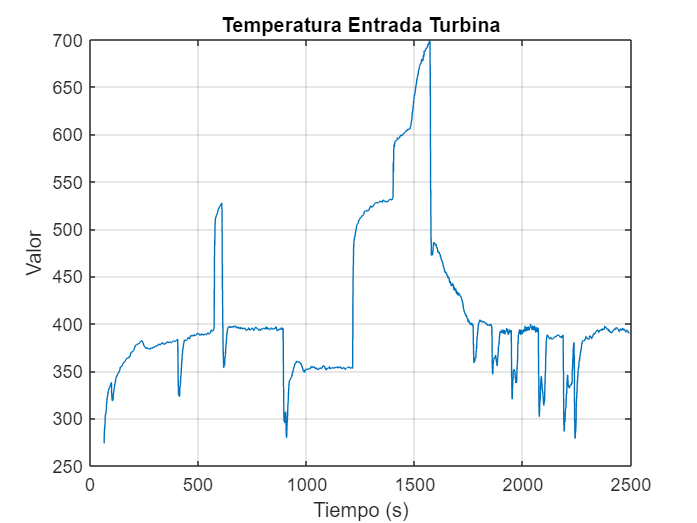

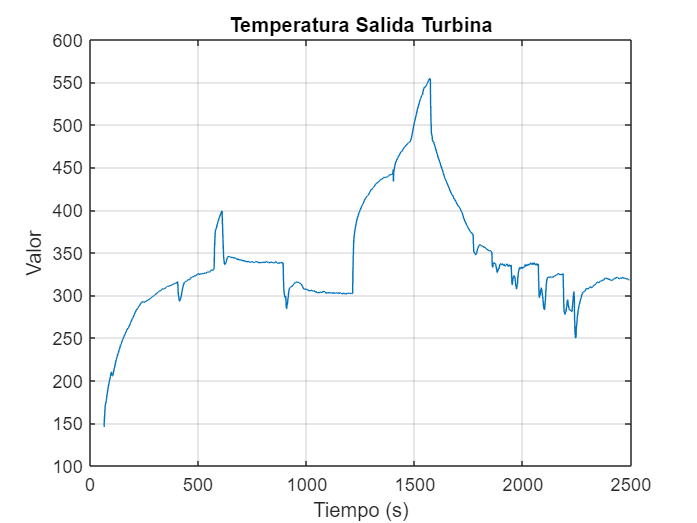

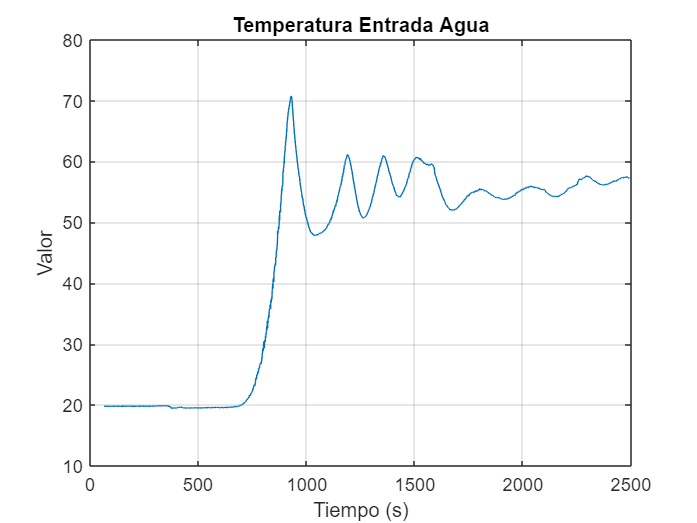

% Extrae la primera columna (Tiempo)
Tiempo = datos{:, 1}; % [s]

% Crear una celda con los nombres de las variables sin guiones bajos
nombres_variables = {'Presion salida intercooler', 'Presion Entrada Turbina', 'Temperatura Ambiente', 'Temperatura Aceite', 'Temperatura Agua Freno', 'Temperatura Entrada Turbina', 'Temperatura Salida Turbina', 'Temperatura Entrada Agua', 'Temperature Salida Agua', 'Temperatura Entrada Intercooler', 'Temperatura Salida Intercooler', 'Temperatura Combustible', 'Presion Salida Compresor', 'Presion Salida Turbina', 'Caudal refrigerante', 'Regimen de giro', 'Caudal Combustible', 'Caudal Admision', 'Temperatura Hilo Admison (V)', 'Par', 'Regimen consigna', 'Carga del pedal', 'Entrada ECU (x2)', 'Entrada ECU', 'Regimen TC', 'Temperatura Después Catalizador', 'Presion Absoluta Ambiente', 'Grado de carga'};

% Iterar sobre cada variable para graficarla
for i = 1:numel(nombres_variables)

    % Crear una nueva figura para cada gráfico
    figure;
    
    % Graficar los datos de la variable actual
    plot(Tiempo, datos{:, i+1}); % Suma 1 para evitar graficar la columna de Tiempo nuevamente
    
    % Etiquetar los ejes y el título del gráfico
    xlabel('Tiempo (s)');
    ylabel('Valor');
    title(nombres_variables{i});
    
    % Mostrar la cuadrícula
    grid on;
end

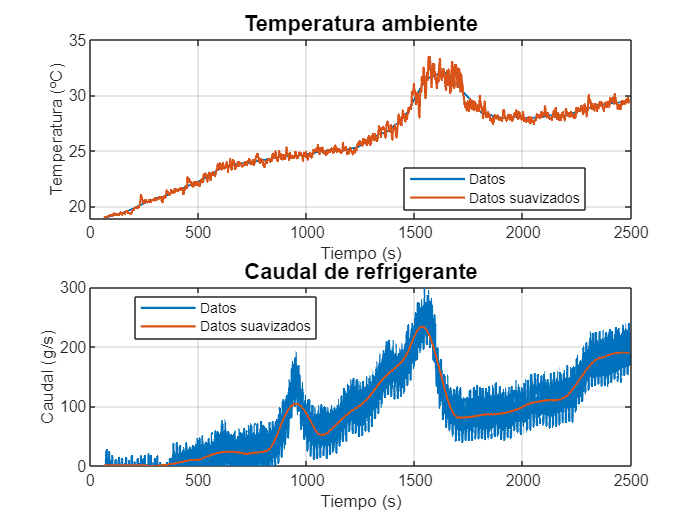


Presion_salida_intercooler = datos{:, 2}; % [bar]
Presion_Entrada_Turbina = datos{:, 3}; % [bar]
Temperatura_Ambiente = datos{:, 4}; % [ºC]
Temperatura_Aceite = datos{:, 5}; % [ºC]
Temperatura_Agua_Freno = datos{:, 6}; % [ºC]
Temperatura_Entrada_Turbina = datos{:, 7}; % [ºC]
Temperatura_Salida_Turbina = datos{:, 8}; % [ºC]
Temperatura_Entrada_Agua = datos{:, 9}; % [ºC]
Temperatura_Salida_Agua = datos{:, 10}; % [ºC]
Temperatura_Entrada_Intercooler = datos{:, 11}; % [ºC]
Temperatura_Salida_Intercooler = datos{:, 12}; % [ºC]
Temperatura_Combustible = datos{:, 13}; % [ºC]
Presion_Salida_Compresor = datos{:, 14}; % [bar]
Presion_Salida_Turbina = datos{:, 15}; % [bar]
Caudal_refrigerante = datos{:, 16}; % [g/s]
Regimen_de_giro = datos{:, 17}; % [rpm]
Caudal_Combustible = datos{:, 18}; % [L/h]
Caudal_Admision = datos{:, 19}; % [g/s]
Temperatura_Hilo_Admison_V = datos{:, 20}; %[ºC]
Par = datos{:, 21}; % [Nm]
Regimen_consigna = datos{:, 22}; % [rpm]
Carga_del_pedal = datos{:, 23}; % [%]
Entrada_ECU_x2 = datos{:, 24}; % [V]
Entrada_ECU = datos{:, 25}; % [V]
Regimen_TC = datos{:, 26}; % [rpm]
Temperatura_Despues_Catalizador = datos{:, 27}; % [ºC]
Presion_Absoluta_Ambiente = datos{:, 28}; % [bar]
Grado_de_carga = datos{:, 29}; % [%]

span = 0.1; % Proporción de puntos utilizados para el suavizado (0 < span < 1)

% Aplicar suavizado a cada variable necesaria
Presion_salida_intercooler = smooth(Tiempo, Presion_salida_intercooler, span, 'sgolay');
Presion_Entrada_Turbina = smooth(Tiempo, Presion_Entrada_Turbina, span, 'sgolay');

Temperatura_Ambiente_suave = smooth(Tiempo, Temperatura_Ambiente, span, 'sgolay');
Temperatura_Ambiente = smooth(Tiempo, Temperatura_Ambiente, span, 'sgolay');

Presion_Salida_Compresor = smooth(Tiempo, Presion_Salida_Compresor, span, 'sgolay');
Presion_Salida_Turbina = smooth(Tiempo, Presion_Salida_Turbina, span, 'sgolay');

Caudal_refrigerante_suave = smooth(Tiempo, Caudal_refrigerante, span, 'sgolay');
Caudal_refrigerante = smooth(Tiempo, Caudal_refrigerante, span, 'sgolay');

Caudal_Combustible = smooth(Tiempo, Caudal_Combustible, span, 'sgolay');
Caudal_Admision = smooth(Tiempo, Caudal_Admision, span, 'sgolay');
Presion_Absoluta_Ambiente = smooth(Tiempo, Presion_Absoluta_Ambiente, span, 'sgolay');

% figure;
% subplot(2,2,[1 2])
% plot(Tiempo, Temperatura_Ambiente_suave, Tiempo, Temperatura_Ambiente, LineWidth=1.2)
% 
% % Configuraciones adicionales
% xlabel('Tiempo (s)');  % Etiqueta del eje X
% ylabel('Temperatura (ºC)')
% legend({'Datos', 'Datos suavizados'}, 'Location', 'best');
% title('Temperatura ambiente', FontSize=12)
% grid on;  % Activar cuadrícula
% 
% subplot(2,2,[3 4])
% plot(Tiempo, Caudal_refrigerante, Tiempo, Caudal_refrigerante_suave, LineWidth=1.2)
% 
% % Configuraciones adicionales
% xlabel('Tiempo (s)');  % Etiqueta del eje X
% ylabel('Caudal (g/s)')
% legend({'Datos', 'Datos suavizados'}, 'Location', 'best');
% title('Caudal de refrigerante', FontSize=12)
% grid on;  % Activar cuadrícula

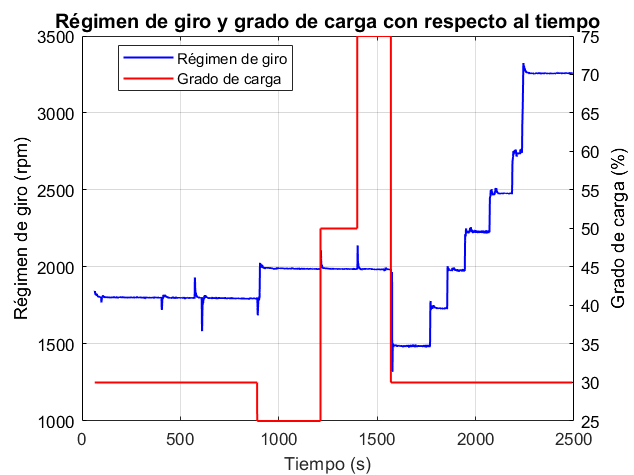


figure;

% Primera gráfica con eje y a la izquierda
yyaxis left
plot(Tiempo, Regimen_de_giro, 'b-', LineWidth=1.2)  % Gráfica en azul
ylabel('Régimen de giro (rpm)')  % Etiqueta del eje y izquierdo

% Cambiar color del eje y izquierdo a negro
ax = gca;
ax.YColor = 'k';

% Segunda gráfica con eje y a la derecha
yyaxis right
plot(Tiempo, Grado_de_carga, 'r-', LineWidth=1.2)  % Gráfica en rojo
ylabel('Grado de carga (%)')  % Etiqueta del eje y derecho

% Cambiar color del eje y derecho a negro
ax.YColor = 'k';

% Configuraciones adicionales
xlabel('Tiempo (s)')  % Etiqueta del eje x
legend({'Régimen de giro', 'Grado de carga'}, 'Location', 'best')
grid on;  % Activar cuadrícula

% Título opcional
title('Régimen de giro y grado de carga con respecto al tiempo', FontSize=12)

## Parte 1: Arranque en frío, estabilización térmica y análisis del balance energético

Mostrar la evolución temporal del balance energético y de temperaturas clave en el proceso de estabilización térmica del motor: temperatura del aceite, del agua de entrada/salida, caudal de bombas, calor evacuado en refrigeración, etc. 

Finalmente, mostrar el balance energético completo a régimen permanente del último punto de operación medido. Justificar el resultado.

**Se estiman de la siguiente manera:**

- Potencia de combustión: $Q_{\textrm{comb}} =\dot{m_F } \;H_c$ 

- Potencia cedido al líquido refrigerante: $Q_{\textrm{refrig}} =\dot{m_{\textrm{ref}} } \;C_{p,\textrm{ref}} \;\left(T_{\textrm{entrada}\;\textrm{intercambiador}} -T_{\textrm{salida}\;\textrm{inercambiador}} \right)$

- Potencia intercambiada en el intercooler: $Q_{\textrm{inter}} =\dot{m_a } \;C_{p,a} \;\left(T_{\textrm{entrada}\;\textrm{intercooler}} -T_{\textrm{salida}\;\textrm{intercooler}} \right)$

- Calor específico de los gases de escape: $C_{p,\textrm{escape}\;} =\frac{\Sigma \;\xi_i \;\;C_{p,i} \;\left(T\right)\;}{\Sigma \;\xi_i \;}$. Siendo \Xi el coeficiente esteq. de i y Cp el calor específico del reactivo i (gases de escape). 

            Siendo la reacción química la siguiente:          

            $C_{12} H_{23} +\frac{71/4}{F_R }(O_2 +3\ldotp 76N_2 )\to 12CO_2 +\frac{23}{2}H_2 O+\frac{3\ldotp 76\cdot \frac{71}{4}}{F_R }N_2 +\frac{71}{4}\cdot \left(\frac{1}{F_R }-1\right)O_2$ .

            En donde: $\xi_{{\textrm{CO}}_2 } =12\;,\;\;\;\;\;\;\;\xi_{H_2 O} =\frac{23}{2},\;\;\;\;\;\xi_{N_2 } =\frac{3\ldotp 76\cdot \frac{71}{4}}{F_R },\;\;\;\;\;\;\;\xi_{O_2 } =\frac{71}{4}\cdot \left(\frac{1}{F_R }-1\right)$

            y para el cálculo de la Cp se utiliza la ecuación de Shomate:

            $C_p =A+B\cdot T+C\cdot T^2 +D\cdot T^3 +\frac{E}{T^2 }$,     en donde cada coeficiente viene dado por el compuesto y el rango de T.

- Potencia cedida por los gases de escape: $Q_{\textrm{gases}} =\dot{m_{\textrm{escape}} \;} C_{p,\textrm{escape}} \;\left(T_{\textrm{salida}\;\textrm{turbina}} -T_{\textrm{entrada}\;\textrm{turbina}} \right)$. 

- Potencia equivalente a la combustión incompleta: $Q_{\textrm{res}} =Q_{\textrm{comb}} -\left(N_e +Q_{\textrm{refrig}} +Q_{\textrm{inter}} +Q_{\textrm{gases}} \right)$

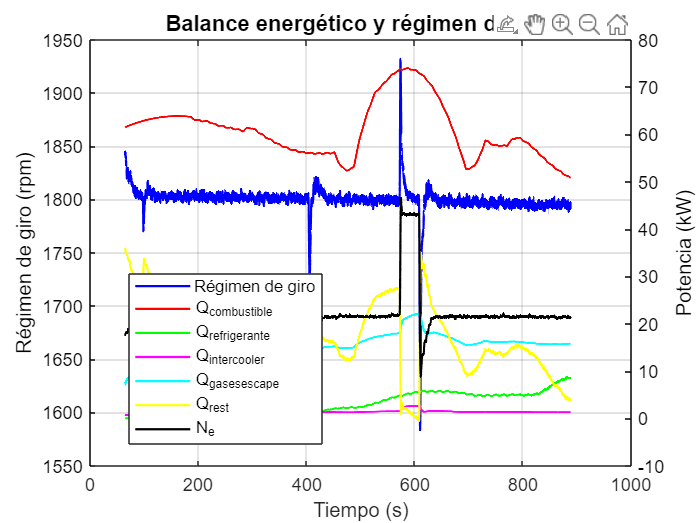

range = (1:8237); %RANGO DE TIEMPO QUE SUCEDE LA PARTE 1

cp_refrig = 3600; % [J/kgK]
cp_aire = 1007; % [J/kgK]
densidad=0.83e3; % [kg/m3]
Hc =43400; % [kJ/kg]
F_e = 1/14.6;
num_cilindros = 4;
carrera = 0.1 ; % carrera del pistón [m]
diametro = 89 * 1e-3; % diámetro del cilindro [m]

V_T = carrera * diametro^2 * num_cilindros * (pi()/4); % [m3]
presion_intercooler = Presion_salida_intercooler + Presion_Absoluta_Ambiente; % [bar]
R_a = 287; % [J /kgK]

dens_a_ref = presion_intercooler .* 1e5 ./ ((Temperatura_Salida_Intercooler + 273.15) .* R_a); % [kg/m3]

% Gráfica 1

mf = densidad .* Caudal_Combustible .* (1e-3/3600); % [kg/s]
ma = Caudal_Admision .* 1e-3; % [kg/s]
mr = Caudal_refrigerante .* 1e-3; % [kg/s]
mgescape = mf + ma; % [kg/s]

% Gráfica 2

% Potencia efectiva
Ne = Par .* Regimen_de_giro .* (pi()/30000); % [kW]
% Consumo específico
gef = (mf .* 1000 .* 3600) ./ Ne; % [g/kWh]
%Presión media efectiva
pme = ((120 .* Ne .* 1e3) ./ (V_T .* Regimen_de_giro)) .* 1e-5; % [Bar]

% Gráfica 3

% Rendimiento volumétrico
rend_vol = (ma .* 120) ./ (V_T .* dens_a_ref .* Regimen_de_giro);
%Rendimiento efectivo
rend_e = Ne ./ (mf .* Hc);
% Dosado relativo
F = mf ./ ma;
F_R = F ./ F_e;

% Coeficientes de Shomate para los compuestos
coeffs.CO2 = [24.99735, 55.18696, -33.69137, 7.948387, -0.136638];
coeffs.H2O = [30.09200, 6.832514, 6.793435, -2.534480, 0.082139];
coeffs.N2_below500K = [28.98641, 1.853978, -9.647459, 16.63537, 0.000117];
coeffs.N2_above500K = [19.50583, 19.88705, -8.598535, 1.369784, 0.527601];
coeffs.O2 = [31.32234, -20.23531, 57.86644, -36.50624, -0.007374];

% Cálculo del Cp_escape
cp_gescape = zeros(24270, 1);
for i = 1:8237
    coef_esteq = [12, 23/2, (3.76.*71/4)./F_R(i), (71./4).*((1./F_R(i))-1)];
    % Temperatura deseada en K
    T = (Temperatura_Salida_Turbina(i) + 273.15); % [K]

    % Verificar si la temperatura es mayor de 500 K para N2
    if T > 500
        A_N2 = coeffs.N2_above500K(1);
        B_N2 = coeffs.N2_above500K(2);
        C_N2 = coeffs.N2_above500K(3);
        D_N2 = coeffs.N2_above500K(4);
        E_N2 = coeffs.N2_above500K(5);
    else
        A_N2 = coeffs.N2_below500K(1);
        B_N2 = coeffs.N2_below500K(2);
        C_N2 = coeffs.N2_below500K(3);
        D_N2 = coeffs.N2_below500K(4);
        E_N2 = coeffs.N2_below500K(5);
    end

    % Calcular Cp para cada compuesto
    cp_CO2 = shomateCp(T, coeffs.CO2(1), coeffs.CO2(2), coeffs.CO2(3), coeffs.CO2(4), coeffs.CO2(5)); % [J/molK]
    cp_H2O = shomateCp(T, coeffs.H2O(1), coeffs.H2O(2), coeffs.H2O(3), coeffs.H2O(4), coeffs.H2O(5)); % [J/molK]
    cp_N2 = shomateCp(T, A_N2, B_N2, C_N2, D_N2, E_N2); % [J/molK]
    cp_O2 = shomateCp(T, coeffs.O2(1), coeffs.O2(2), coeffs.O2(3), coeffs.O2(4), coeffs.O2(5)); % [J/molK]

    cp_gescape(i, 1) = ((coef_esteq(1).* cp_CO2 ./ 44) + (coef_esteq(2).* cp_H2O ./ 18) + (coef_esteq(3).* cp_N2 ./ 28) +(coef_esteq(4).* cp_O2 ./ 32)) ./ (sum(coef_esteq)); % [kJ/kgK]
end

Q_comb = mf .* Hc; % [kW]
Q_refrig = mr .* cp_refrig .* (Temperatura_Salida_Agua - Temperatura_Entrada_Agua) .* 1e-3; % [kW]
Q_intercooler = ma .* cp_aire .* (Temperatura_Entrada_Intercooler - Temperatura_Salida_Intercooler) .* 1e-3; % [kW]
Q_gasesescape = mgescape .* cp_gescape .* (Temperatura_Salida_Turbina - Temperatura_Ambiente); % [kW]
Q_rest = Q_comb-(Ne+Q_refrig+Q_intercooler+Q_gasesescape);

figure;

% Primera gráfica con eje Y a la izquierda
yyaxis left
plot(Tiempo(range), Regimen_de_giro(range), 'b-', 'LineWidth', 1.2);  % Gráfica en azul
ylabel('Régimen de giro (rpm)');  % Etiqueta del eje Y izquierdo

% Cambiar color del eje Y izquierdo a negro
ax = gca;
ax.YColor = 'k';

% Segunda gráfica con eje Y a la derecha
yyaxis right
plot(Tiempo(range), Q_comb(range), 'r-', 'LineWidth', 1.2);  % Gráfica en rojo
hold on;
plot(Tiempo(range), Q_refrig(range), 'g-', 'LineWidth', 1.2);  % Gráfica en verde
plot(Tiempo(range), Q_intercooler(range), 'm-', 'LineWidth', 1.2);  % Gráfica en magenta
plot(Tiempo(range), Q_gasesescape(range), 'c-', 'LineWidth', 1.2);  % Gráfica en cian
plot(Tiempo(range), Q_rest(range), 'y-', 'LineWidth', 1.2);  % Gráfica en amarillo
plot(Tiempo(range), Ne(range), 'k-', 'LineWidth', 1.2);  % Gráfica en negro
hold off;

% Etiqueta para el segundo eje Y
ylabel('Potencia (kW)');

% Cambiar color del eje Y derecho a negro
ax.YColor = 'k';

% Configuraciones adicionales
xlabel('Tiempo (s)');  % Etiqueta del eje X
legend({'Régimen de giro', 'Q_{combustible}', 'Q_{refrigerante}', 'Q_{intercooler}', 'Q_{gasesescape}', 'Q_{rest}', 'N_e'}, 'Location', 'best');
grid on;  % Activar cuadrícula

% Título del gráfico
title('Balance energético y régimen de giro', 'FontSize', 12);

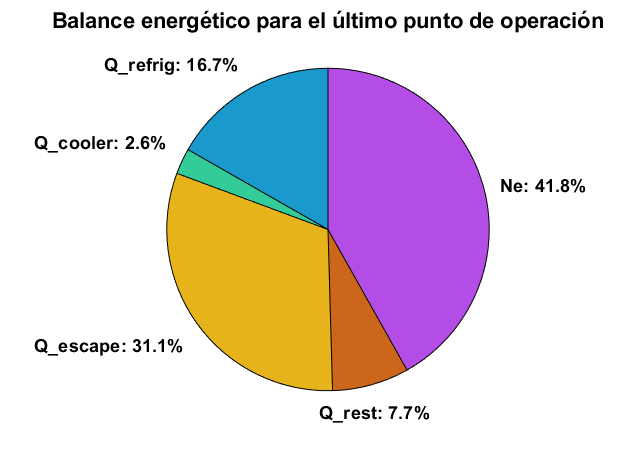


%Cálculo de porcentajes del último punto de operación medido

% Obtener los últimos valores en el rango especificado
Q_comb_last = Q_comb(range(end));
Q_refrig_last = Q_refrig(range(end));
Q_intercooler_last = Q_intercooler(range(end));
Q_gasesescape_last = Q_gasesescape(range(end));
Q_rest_last = Q_rest(range(end));
Ne_last = Ne(range(end));

% Calcular la potencia total
Q_total = Q_comb_last;

% Calcular los porcentajes de cada componente
percent_refrig = (Q_refrig_last / Q_total) * 100;
percent_intercooler = (Q_intercooler_last / Q_total) * 100;
percent_gasesescape = (Q_gasesescape_last / Q_total) * 100;
percent_rest = (Q_rest_last / Q_total) * 100;
percent_Ne = (Ne_last / Q_total) * 100;

% Crear el vector de datos para el gráfico de pastel
data = [percent_refrig, percent_intercooler, percent_gasesescape, percent_rest, percent_Ne];

% Crear el gráfico de pastel
figure;
% Crear las etiquetas con formato
labels = {
    sprintf('Q\\_refrig: %.1f%%', percent_refrig);
    sprintf('Q\\_cooler: %.1f%%', percent_intercooler);
    sprintf('Q\\_escape: %.1f%%', percent_gasesescape);
    sprintf('Q\\_rest: %.1f%%', percent_rest);
    sprintf('Ne: %.1f%%', percent_Ne)
};

% Especificar los colores para cada segmento
colors = [
    0.1, 0.6, 0.8;  % color para Q_refrig
    0.2, 0.8, 0.6;  % color para Q_intercooler
    0.9, 0.7, 0.1;  % color para Q_gasesescape
    0.8, 0.4, 0.1;  % color para Q_rest
    0.7, 0.3, 0.9;  % color para Ne
];

% Crear el gráfico de pastel con sectores destacados
figure;
p = pie(data);

% Asignar colores a los sectores
h = findobj(p, 'Type', 'Patch');
for k = 1:length(h)
    h(k).FaceColor = colors(k, :);
end

% Añadir las etiquetas estilizadas
hText = findobj(p, 'Type', 'text');
percentValues = get(hText, 'String'); 
for k = 1:length(hText)
    hText(k).String = labels{k};
    hText(k).FontSize = 11;
    hText(k).FontWeight = 'bold';
end

% Añadir título al gráfico
title('Balance energético para el último punto de operación', 'FontSize', 13, 'FontWeight', 'bold');

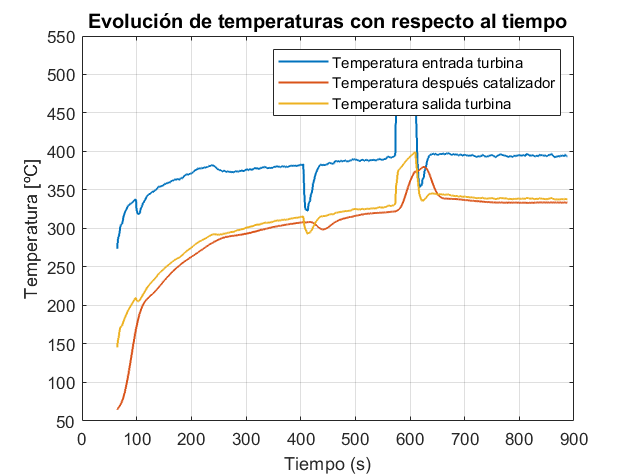


% Primer gráfico: Temperatura Entrada Turbina, Después Catalizador, Salida Turbina
figure;

plot(Tiempo(range), Temperatura_Entrada_Turbina(range), 'DisplayName', 'Temperatura entrada turbina', LineWidth=1.2);
hold on;
plot(Tiempo(range), Temperatura_Despues_Catalizador(range), 'DisplayName', 'Temperatura después catalizador', LineWidth=1.2);
plot(Tiempo(range), Temperatura_Salida_Turbina(range), 'DisplayName', 'Temperatura salida turbina', LineWidth=1.2);

% Añadir la leyenda
legend('show');

% Añadir títulos y etiquetas
title('Evolución de temperaturas con respecto al tiempo', FontSize=12);
xlabel('Tiempo (s)');
ylabel('Temperatura [ºC]');

% Mejorar la visualización
grid on;
hold off;

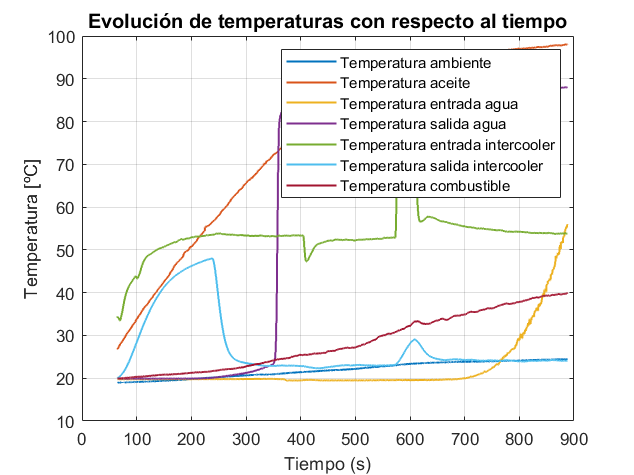


% Segundo gráfico: Resto de las temperaturas
figure;

plot(Tiempo(range), Temperatura_Ambiente(range), 'DisplayName', 'Temperatura ambiente', LineWidth=1.2);
hold on;
plot(Tiempo(range), Temperatura_Aceite(range), 'DisplayName', 'Temperatura aceite', LineWidth=1.2);
plot(Tiempo(range), Temperatura_Entrada_Agua(range), 'DisplayName', 'Temperatura entrada agua', LineWidth=1.2);
plot(Tiempo(range), Temperatura_Salida_Agua(range), 'DisplayName', 'Temperatura salida agua', LineWidth=1.2);
plot(Tiempo(range), Temperatura_Entrada_Intercooler(range), 'DisplayName', 'Temperatura entrada intercooler', LineWidth=1.2);
plot(Tiempo(range), Temperatura_Salida_Intercooler(range), 'DisplayName', 'Temperatura salida intercooler', LineWidth=1.2);
plot(Tiempo(range), Temperatura_Combustible(range), 'DisplayName', 'Temperatura combustible', LineWidth=1.2);

% Añadir la leyenda
legend('show');

% Añadir títulos y etiquetas
title('Evolución de temperaturas con respecto al tiempo',FontSize=12);
xlabel('Tiempo (s)');
ylabel('Temperatura [ºC]');

% Mejorar la visualización
grid on;
hold off;

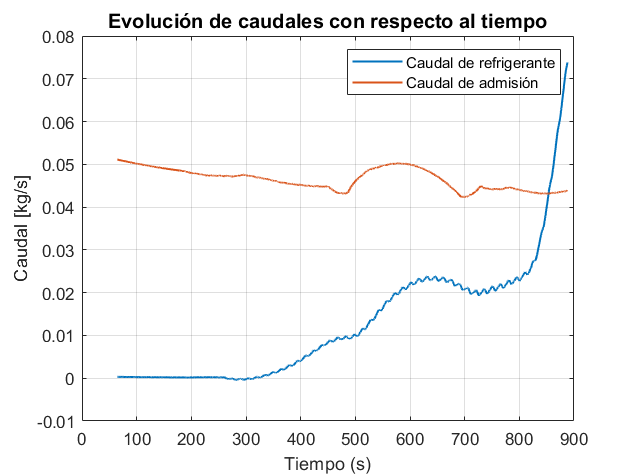


figure;

%Gráficos de caudales
plot(Tiempo(range), mr(range), Tiempo(range), ma(range), LineWidth=1.2)

% Añadir títulos y etiquetas
title('Evolución de caudales con respecto al tiempo', FontSize=12);
xlabel('Tiempo (s)');
ylabel('Caudal [kg/s]');
legend('Caudal de refrigerante', 'Caudal de admisión')

grid on;

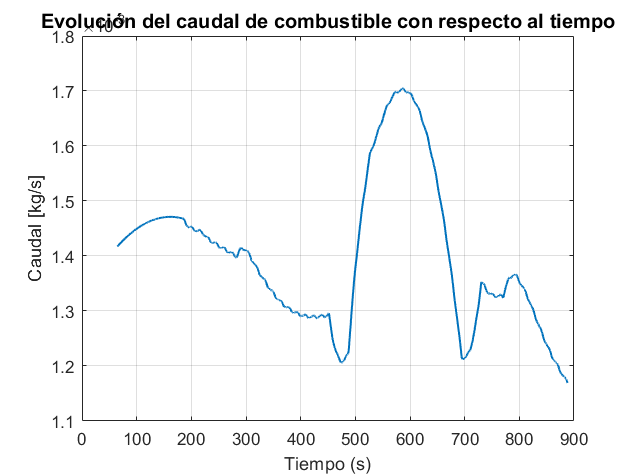


figure;

% Caudal de combustible
plot(Tiempo(range), mf(range), LineWidth=1.2)

% Añadir títulos y etiquetas
title('Evolución del caudal de combustible con respecto al tiempo', FontSize=12);
xlabel('Tiempo (s)');
ylabel('Caudal [kg/s]');

grid on;

## Parte 2: Ensayos a régimen de giro constante

Mostrar la evolución de parámetros como: par, potencia, pme, dosado relativo, temperatura de escape, gasto de combustible, consumo especifico de combustible, gasto de aire, rendimiento volumétrico y el rendimiento efectivo.

**Fórmulas utilizadas:**

- Volumen total: $V_T =\frac{s\;z\;\pi \;D^2 \;\;}{4}$. Siendo s la carrera, z el número de cilindros y D el diámetro del cilindro.

- Densidad de referencia: $\rho_{\textrm{REF}} =\frac{P_{\textrm{intercooler}\;\textrm{salida}} \;\;\;}{R\;T_{\textrm{salida}\;\textrm{intercooler}} }$.

- Caudal másico del combustible: $\dot{m_F } =\rho_F \;\dot{V_F } \;$.

- Caudal másico de escape: $\dot{m_{\textrm{escape}} } =\dot{m_F } -\dot{m_a } \;\;$. Donde m_a es el caudal másico de admisión.

- Potencia efectiva: $N_e =M\;2\;\pi \;n$. Siendo M el par y n la frecuencia.

- Consumo específico: $g_{\textrm{ef}} =\dot{\frac{m_F }{N_e }}$.

- Rendimiento efectivo: $\eta_e =\frac{N_e }{\dot{m_F \;} H_c }$. Siendo H_c el poder calorífico del combustible.

- Dosado: $F=\dot{\frac{m_F }{\dot{m_a } }}$.

- Dosado relativo: $F_R =\frac{F}{F_e }$. Siendo F_e el dosado estequiométrico.

- Rendimiento volumétrico: $\eta_V =\dot{\frac{m_a }{\rho_{\textrm{REF}} \;V_T \;\frac{n}{2}}}$.

- Presión media efectiva: ${\textrm{Pm}}_e =\frac{N_e }{V_T \frac{n}{2}}$.

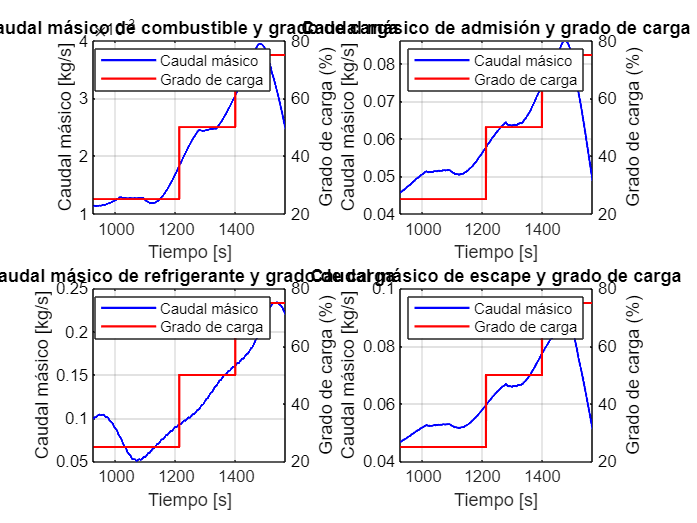

% Los cálculos de las variables anteriores mencionadas se calculan
% anteriormente en la parte 1 del ensayo.

range2 = (8608: 15029); %RANGO DE TIEMPO QUE SUCEDE LA PARTE 2

% Gráfica 1
figure;

% Graficar mf con Grado_de_carga
subplot(2,2,1);
yyaxis left
plot(Tiempo(range2), mf(range2), 'b-',LineWidth=1.2);
ylabel('Caudal másico [kg/s]');
ax = gca;
ax.YColor = 'k';
yyaxis right
plot(Tiempo(range2), Grado_de_carga(range2), 'r-',LineWidth=1.2);
ylabel('Grado de carga (%)');
ax.YColor = 'k';
title('Caudal másico de combustible y grado de carga');
xlabel('Tiempo [s]');
legend({'Caudal másico', 'Grado de carga'}, 'Location', 'best');
grid on;

% Graficar ma con Grado_de_carga
subplot(2,2,2);
yyaxis left
plot(Tiempo(range2), ma(range2), 'b-',LineWidth=1.2);
ylabel('Caudal másico [kg/s]');
ax = gca;
ax.YColor = 'k';
yyaxis right
plot(Tiempo(range2), Grado_de_carga(range2), 'r-',LineWidth=1.2);
ylabel('Grado de carga (%)');
ax.YColor = 'k';
title('Caudal másico de admisión y grado de carga');
xlabel('Tiempo [s]');
legend({'Caudal másico', 'Grado de carga'}, 'Location', 'best');
grid on;

% Graficar mr con Grado_de_carga
subplot(2,2,3);
yyaxis left
plot(Tiempo(range2), mr(range2), 'b-',LineWidth=1.2);
ylabel('Caudal másico [kg/s]');
ax = gca;
ax.YColor = 'k';
yyaxis right
plot(Tiempo(range2), Grado_de_carga(range2), 'r-',LineWidth=1.2);
ylabel('Grado de carga (%)');
ax.YColor = 'k';
title('Caudal másico de refrigerante y grado de carga');
xlabel('Tiempo [s]');
legend({'Caudal másico', 'Grado de carga'}, 'Location', 'best');
grid on;

% Graficar mgescape con Grado_de_carga
subplot(2,2,4);
yyaxis left
plot(Tiempo(range2), mgescape(range2), 'b-',LineWidth=1.2);
ylabel('Caudal másico [kg/s]');
ax = gca;
ax.YColor = 'k';
yyaxis right
plot(Tiempo(range2), Grado_de_carga(range2), 'r-',LineWidth=1.2);
ylabel('Grado de carga (%)');
ax.YColor = 'k';
title('Caudal másico de escape y grado de carga');
xlabel('Tiempo [s]');
legend({'Caudal másico', 'Grado de carga'}, 'Location', 'best');
grid on;

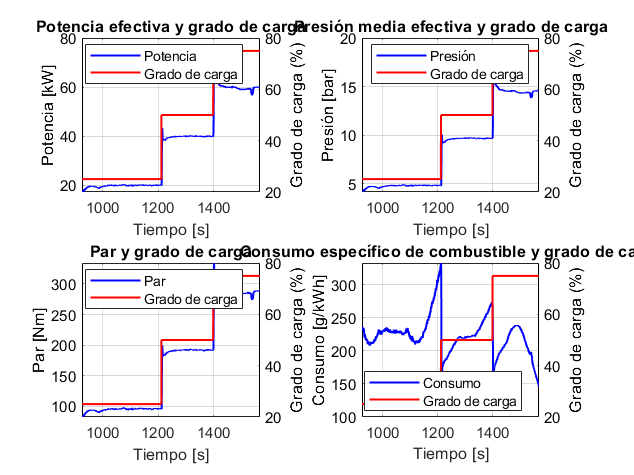


% Gráfica 2
figure; 

% Graficar Ne con Grado_de_carga
subplot(2,2,1);
yyaxis left
plot(Tiempo(range2), Ne(range2), 'b-',LineWidth=1.2);
ylabel('Potencia [kW]');
ax = gca;
ax.YColor = 'k';
yyaxis right
plot(Tiempo(range2), Grado_de_carga(range2), 'r-',LineWidth=1.2);
ylabel('Grado de carga (%)');
ax.YColor = 'k';
title('Potencia efectiva y grado de carga');
xlabel('Tiempo [s]');
legend({'Potencia', 'Grado de carga'}, 'Location', 'best');
grid on;

% Graficar pme con Grado_de_carga
subplot(2,2,2);
yyaxis left
plot(Tiempo(range2), pme(range2), 'b-',LineWidth=1.2);
ylabel('Presión [bar]');
ax = gca;
ax.YColor = 'k';
yyaxis right
plot(Tiempo(range2), Grado_de_carga(range2), 'r-',LineWidth=1.2);
ylabel('Grado de carga (%)');
ax.YColor = 'k';
title('Presión media efectiva y grado de carga');
xlabel('Tiempo [s]');
legend({'Presión', 'Grado de carga'}, 'Location', 'best');
grid on;

% Graficar Par con Grado_de_carga
subplot(2,2,3);
yyaxis left
plot(Tiempo(range2), Par(range2), 'b-',LineWidth=1.2);
ylabel('Par [Nm]');
ax = gca;
ax.YColor = 'k';
yyaxis right
plot(Tiempo(range2), Grado_de_carga(range2), 'r-',LineWidth=1.2);
ylabel('Grado de carga (%)');
ax.YColor = 'k';
title('Par y grado de carga');
xlabel('Tiempo [s]');
legend({'Par', 'Grado de carga'}, 'Location', 'best');
grid on;

% Graficar gef con Grado_de_carga
subplot(2,2,4);
yyaxis left
plot(Tiempo(range2), gef(range2), 'b-',LineWidth=1.2);
ylabel('Consumo [g/kWh]');
ax = gca;
ax.YColor = 'k';
yyaxis right
plot(Tiempo(range2), Grado_de_carga(range2), 'r-',LineWidth=1.2);
ylabel('Grado de carga (%)');
ax.YColor = 'k';
title('Consumo específico de combustible y grado de carga');
xlabel('Tiempo [s]');
legend({'Consumo', 'Grado de carga'}, 'Location', 'best');
grid on;

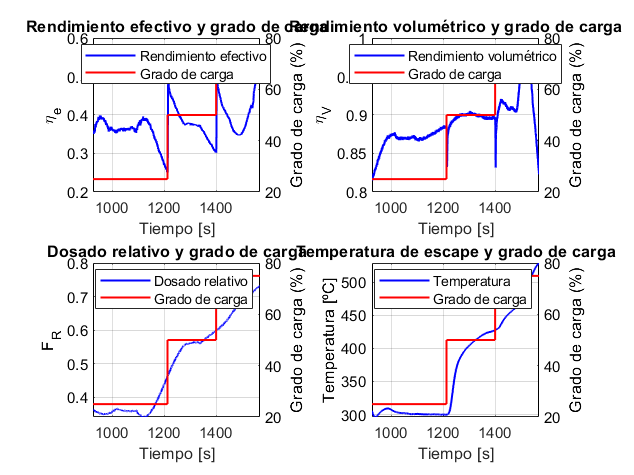


% Gráfica 3
figure; 

% Graficar rend_e con Grado_de_carga
subplot(2,2,1);
yyaxis left
plot(Tiempo(range2), rend_e(range2), 'b-',LineWidth=1.2);
ylabel('\eta_e');
ax = gca;
ax.YColor = 'k';
yyaxis right
plot(Tiempo(range2), Grado_de_carga(range2), 'r-',LineWidth=1.2);
ylabel('Grado de carga (%)');
ax.YColor = 'k';
title('Rendimiento efectivo y grado de carga');
xlabel('Tiempo [s]');
legend({'Rendimiento efectivo', 'Grado de carga'}, 'Location', 'best');
grid on;

% Graficar rend_vol con Grado_de_carga
subplot(2,2,2);
yyaxis left
plot(Tiempo(range2), rend_vol(range2), 'b-',LineWidth=1.2);
ylabel('\eta_V');
ax = gca;
ax.YColor = 'k';
yyaxis right
plot(Tiempo(range2), Grado_de_carga(range2), 'r-',LineWidth=1.2);
ylabel('Grado de carga (%)');
ax.YColor = 'k';
title('Rendimiento volumétrico y grado de carga');
xlabel('Tiempo [s]');
legend({'Rendimiento volumétrico', 'Grado de carga'}, 'Location', 'best');
grid on;

% Graficar F_R con Grado_de_carga
subplot(2,2,3);
yyaxis left
plot(Tiempo(range2), F_R(range2), 'b-',LineWidth=1.2);
ylabel('F_R');
ax = gca;
ax.YColor = 'k';
yyaxis right
plot(Tiempo(range2), Grado_de_carga(range2), 'r-',LineWidth=1.2);
ylabel('Grado de carga (%)');
ax.YColor = 'k';
title('Dosado relativo y grado de carga');
xlabel('Tiempo [s]');
legend({'Dosado relativo', 'Grado de carga'}, 'Location', 'best');
grid on;

% Graficar Temperatura_Despues_Catalizador con Grado_de_carga
subplot(2,2,4);
yyaxis left
plot(Tiempo(range2), Temperatura_Despues_Catalizador(range2), 'b-',LineWidth=1.2);
ylabel('Temperatura [ºC]');
ax = gca;
ax.YColor = 'k';
yyaxis right
plot(Tiempo(range2), Grado_de_carga(range2), 'r-',LineWidth=1.2);
ylabel('Grado de carga (%)');
ax.YColor = 'k';
title('Temperatura de escape y grado de carga');
xlabel('Tiempo [s]');
legend({'Temperatura', 'Grado de carga'}, 'Location', 'best');
grid on;

## Parte 3: Ensayos a grado de acelerador constante.

Mostrar la evolución de parámetros como: par, potencia, pme, dosado relativo, temperatura de escape, gasto de combustible, consumo especifico de combustible, gasto de aire, rendimiento volumétrico y el rendimiento efectivo.

Las fórmulas son las mismas que las de la parte 2.

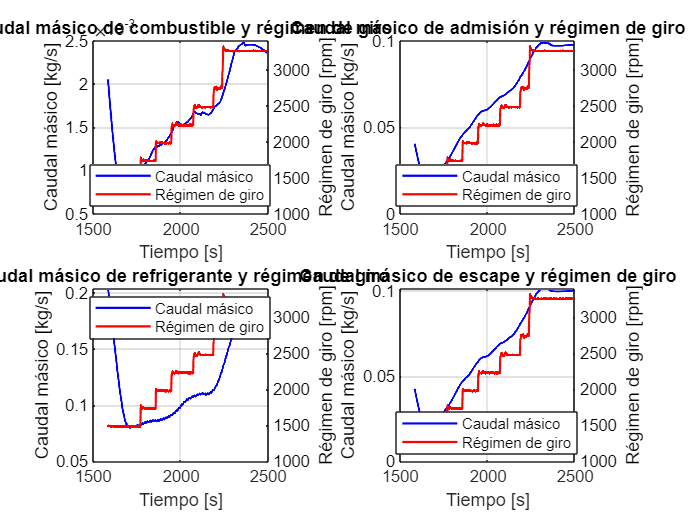

range3=(15185:24270); % RANGO DE TIEMPO QUE SUCEDE LA PARTE3

% Gráfica 1
figure;

% Graficar mf con Regimen_de_giro
subplot(2,2,1);
yyaxis left
plot(Tiempo(range3), mf(range3), 'b-',LineWidth=1.2);
ylabel('Caudal másico [kg/s]');
ax = gca;
ax.YColor = 'k';
yyaxis right
plot(Tiempo(range3), Regimen_de_giro(range3), 'r-',LineWidth=1.2);
ylabel('Régimen de giro [rpm]');
ax.YColor = 'k';
title('Caudal másico de combustible y régimen de giro');
xlabel('Tiempo [s]');
legend({'Caudal másico', 'Régimen de giro'}, 'Location', 'best');
grid on;

% Graficar ma con Regimen_de_giro
subplot(2,2,2);
yyaxis left
plot(Tiempo(range3), ma(range3), 'b-',LineWidth=1.2);
ylabel('Caudal másico [kg/s]');
ax = gca;
ax.YColor = 'k';
yyaxis right
plot(Tiempo(range3), Regimen_de_giro(range3), 'r-',LineWidth=1.2);
ylabel('Régimen de giro [rpm]');
ax.YColor = 'k';
title('Caudal másico de admisión y régimen de giro');
xlabel('Tiempo [s]');
legend({'Caudal másico', 'Régimen de giro'}, 'Location', 'best');
grid on;

% Graficar mr con Regimen_de_giro
subplot(2,2,3);
yyaxis left
plot(Tiempo(range3), mr(range3), 'b-',LineWidth=1.2);
ylabel('Caudal másico [kg/s]');
ax = gca;
ax.YColor = 'k';
yyaxis right
plot(Tiempo(range3), Regimen_de_giro(range3), 'r-',LineWidth=1.2);
ylabel('Régimen de giro [rpm]');
ax.YColor = 'k';
title('Caudal másico de refrigerante y régimen de giro');
xlabel('Tiempo [s]');
legend({'Caudal másico', 'Régimen de giro'}, 'Location', 'best');
grid on;

% Graficar mgescape con Regimen_de_giro
subplot(2,2,4);
yyaxis left
plot(Tiempo(range3), mgescape(range3), 'b-',LineWidth=1.2);
ylabel('Caudal másico [kg/s]');
ax = gca;
ax.YColor = 'k';
yyaxis right
plot(Tiempo(range3), Regimen_de_giro(range3), 'r-',LineWidth=1.2);
ylabel('Régimen de giro [rpm]');
ax.YColor = 'k';
title('Caudal másico de escape y régimen de giro');
xlabel('Tiempo [s]');
legend({'Caudal másico', 'Régimen de giro'}, 'Location', 'best');
grid on;

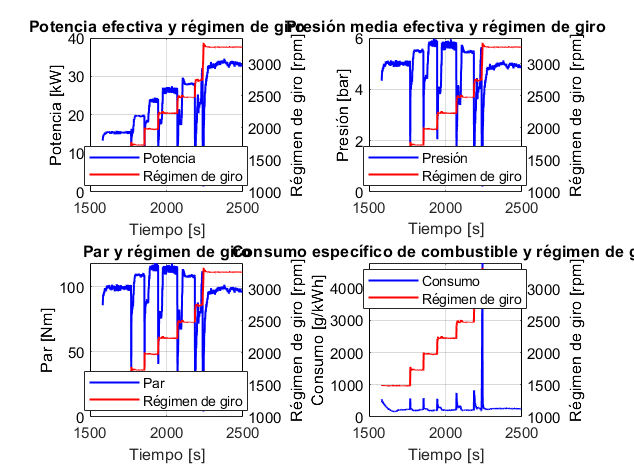


% Gráfica 2
figure; 

% Graficar Ne con Regimen_de_giro
subplot(2,2,1);
yyaxis left
plot(Tiempo(range3), Ne(range3), 'b-',LineWidth=1.2);
ylabel('Potencia [kW]');
ax = gca;
ax.YColor = 'k';
yyaxis right
plot(Tiempo(range3), Regimen_de_giro(range3), 'r-',LineWidth=1.2);
ylabel('Régimen de giro [rpm]');
ax.YColor = 'k';
title('Potencia efectiva y régimen de giro');
xlabel('Tiempo [s]');
legend({'Potencia', 'Régimen de giro'}, 'Location', 'best');
grid on;

% Graficar pme con Regimen_de_giro
subplot(2,2,2);
yyaxis left
plot(Tiempo(range3), pme(range3), 'b-',LineWidth=1.2);
ylabel('Presión [bar]');
ax = gca;
ax.YColor = 'k';
yyaxis right
plot(Tiempo(range3), Regimen_de_giro(range3), 'r-',LineWidth=1.2);
ylabel('Régimen de giro [rpm]');
ax.YColor = 'k';
title('Presión media efectiva y régimen de giro');
xlabel('Tiempo [s]');
legend({'Presión', 'Régimen de giro'}, 'Location', 'best');
grid on;

% Graficar Par con Regimen_de_giro
subplot(2,2,3);
yyaxis left
plot(Tiempo(range3), Par(range3), 'b-',LineWidth=1.2);
ylabel('Par [Nm]');
ax = gca;
ax.YColor = 'k';
yyaxis right
plot(Tiempo(range3), Regimen_de_giro(range3), 'r-',LineWidth=1.2);
ylabel('Régimen de giro [rpm]');
ax.YColor = 'k';
title('Par y régimen de giro');
xlabel('Tiempo [s]');
legend({'Par', 'Régimen de giro'}, 'Location', 'best');
grid on;

% Graficar gef con Regimen_de_giro
subplot(2,2,4);
yyaxis left
plot(Tiempo(range3), gef(range3), 'b-',LineWidth=1.2);
ylabel('Consumo [g/kWh]');
ax = gca;
ax.YColor = 'k';
yyaxis right
plot(Tiempo(range3), Regimen_de_giro(range3), 'r-',LineWidth=1.2);
ylabel('Régimen de giro [rpm]');
ax.YColor = 'k';
title('Consumo específico de combustible y régimen de giro');
xlabel('Tiempo [s]');
legend({'Consumo', 'Régimen de giro'}, 'Location', 'best');
grid on;

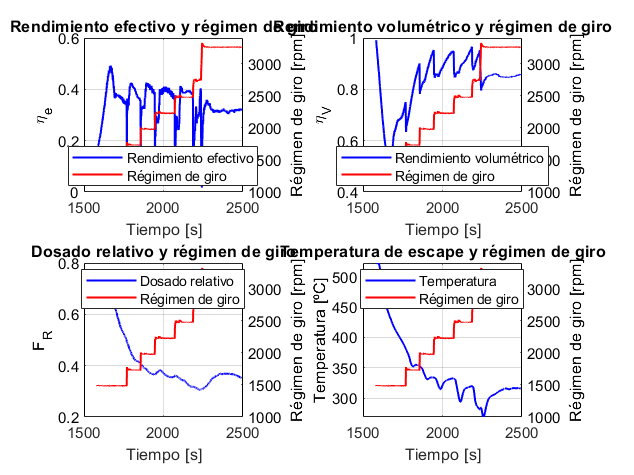


% Gráfica 3
figure; 

% Graficar rend_e con Regimen_de_giro
subplot(2,2,1);
yyaxis left
plot(Tiempo(range3), rend_e(range3), 'b-',LineWidth=1.2);
ylabel('\eta_e');
ax = gca;
ax.YColor = 'k';
yyaxis right
plot(Tiempo(range3), Regimen_de_giro(range3), 'r-',LineWidth=1.2);
ylabel('Régimen de giro [rpm]');
ax.YColor = 'k';
title('Rendimiento efectivo y régimen de giro');
xlabel('Tiempo [s]');
legend({'Rendimiento efectivo', 'Régimen de giro'}, 'Location', 'best');
grid on;

% Graficar rend_vol con Regimen_de_giro
subplot(2,2,2);
yyaxis left
plot(Tiempo(range3), rend_vol(range3), 'b-',LineWidth=1.2);
ylabel('\eta_V');
ax = gca;
ax.YColor = 'k';
yyaxis right
plot(Tiempo(range3), Regimen_de_giro(range3), 'r-',LineWidth=1.2);
ylabel('Régimen de giro [rpm]');
ax.YColor = 'k';
title('Rendimiento volumétrico y régimen de giro');
xlabel('Tiempo [s]');
legend({'Rendimiento volumétrico', 'Régimen de giro'}, 'Location', 'best');
grid on;

% Graficar F_R con Regimen_de_giro
subplot(2,2,3);
yyaxis left
plot(Tiempo(range3), F_R(range3), 'b-',LineWidth=1.2);
ylabel('F_R');
ax = gca;
ax.YColor = 'k';
yyaxis right
plot(Tiempo(range3), Regimen_de_giro(range3), 'r-',LineWidth=1.2);
ylabel('Régimen de giro [rpm]');
ax.YColor = 'k';
title('Dosado relativo y régimen de giro');
xlabel('Tiempo [s]');
legend({'Dosado relativo', 'Régimen de giro'}, 'Location', 'best');
grid on;

% Graficar Temperatura_Despues_Catalizador con Regimen_de_giro
subplot(2,2,4);
yyaxis left
plot(Tiempo(range3), Temperatura_Despues_Catalizador(range3), 'b-',LineWidth=1.2);
ylabel('Temperatura [ºC]');
ax = gca;
ax.YColor = 'k';
yyaxis right
plot(Tiempo(range3), Regimen_de_giro(range3), 'r-',LineWidth=1.2);
ylabel('Régimen de giro [rpm]');
ax.YColor = 'k';
title('Temperatura de escape y régimen de giro');
xlabel('Tiempo [s]');
legend({'Temperatura', 'Régimen de giro'}, 'Location', 'best');
grid on;

## Ecuación de Shomate

Esta ecuación se encarga de calcular las calores específicos de cualquier elemento/compuesto químico en función de su temperatura. Los coeficientes se pueden encontrar en https://webbook.nist.gov/.

function cp = shomateCp(T, A, B, C, D, E)
    % Calcula Cp utilizando la ecuación de Shomate
    cp = A + B * (T/1000) + C * (T/1000)^2 + D * (T/1000)^3 + E / (T/1000)^2;
end